# The Bisection Method

## Calculate inital values for variables

Create brackets

xp = -0.5;
xn = 0.8;

Calculate the midpoint

xmp = (xn+xp)/2;

Calculate 

ymp = 0.5 - sin(xmp) - xmp.^2;

## Define the Bisection Method

### Task1

In the previous activity, this rule was established to update the brackets:

If ymp is less than 0, then xneg=xmp.

If ymp is greater than 0, then xpos=xmp.

The rule can be implemented as an `if`/`else` statement in MATLAB.

Task

The second section of the script implements the bisection method algorithm. 

Complete the `if`/`else` statement it contains to update the brackets `xn` and `xp` based on the value of `ymp`.

You can get better accuracy by changing the number of `for` loop iterations, but what if you want the method to repeat until 

ymp

 was close enough to zero?

**Task 2**

For any value of `n`, you can repeat code `n` times using a `for` loop.

`for` `i` `=` `1``:``n`

`% Do something`

`end`

The script repeats the bisection method using a `for` loop, and the value chosen for `n` in the `for` loop determines the accuracy of the root.

Task

Increase the number of `for` loop iterations so that the final value of `ymp` is less than 0.001.

for iteration = 1:10
    if ymp < 0
        % ymp is less than zero
        xn=xmp
    else
        % ymp is greater than zero
        xp=xmp
    end
    xmp = (xn + xp) / 2;
    ymp = 0.5 - sin(xmp) - xmp.^2;
end

xp = 0.1500

xn = 0.4750

xp = 0.3125

xn = 0.3938

xp = 0.3531

xn = 0.3734

xp = 0.3633

xp = 0.3684

xn = 0.3709

xp = 0.3696

**Further Practice**

You can repeat the bisection method until `ymp` is a certain value using a `while` loop.

Change the line `for` `iteration` `=` `1``:``10`to`while` `abs``(``ymp``)` `>` `0.001`

 and rerun the script using the **Run** button.

By changing the value of `0.001` in the `while` loop, you can repeat the bisection method until it achieves a desired error tolerance.

You can read more about `while` loops in the documentation.

while abs(ymp) >0.001
    if ymp < 0
        % ymp is less than zero
        xn=xmp
    else
        % ymp is greater than zero
        xp=xmp
    end
    xmp = (xn + xp) / 2;
    ymp = 0.5 - sin(xmp) - xmp.^2;
end

xp = 0.3703

## Display the root value

xmp

xmp = 0.3706

ymp

ymp = 5.1258e-04

Plot the function and the root

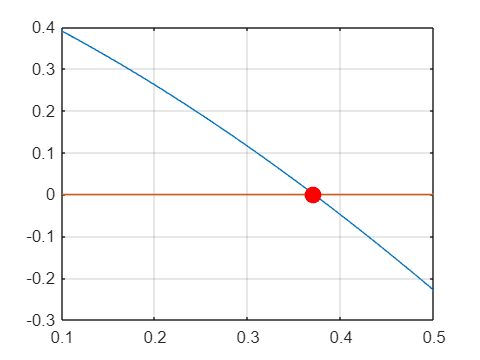

xvals = linspace(0.1,0.5);
yvals = 0.5 - sin(xvals) - xvals.^2;
plot(xvals,yvals)
hold on
plot([0.1 0.5],[0 0])
plot(xmp,ymp,"r.","MarkerSize",30)
hold off
grid on